# ZEN vs 時間相関プログラム

POINT = sprintf("x=%d", constant_X);
addpath(genpath("zen"));
zen_matrix = readmatrix(sprintf("zen/%s/%s.txt",DATE, beads_size));
row = find((zen_matrix(:,1) > TIME_SCALE) & (zen_matrix(:,1) < TIME_SCALE*TAU_MAX))

row =     79
    80
    81
    82
    83
    84
    85
    86
    87
    88


zen_matrix_extracted = zen_matrix(row, :)

zen_matrix_extracted =     0.0008    1.1990
    0.0008    1.1924
    0.0009    1.1820
    0.0010    1.1728
    0.0011    1.1644
    0.0012    1.1572
    0.0013    1.1507
    0.0014    1.1444
    0.0015    1.1377
    0.0016    1.1325


TAU_zen = zen_matrix_extracted(:,1); 
COR_zen = zen_matrix_extracted(:,2);

プロット

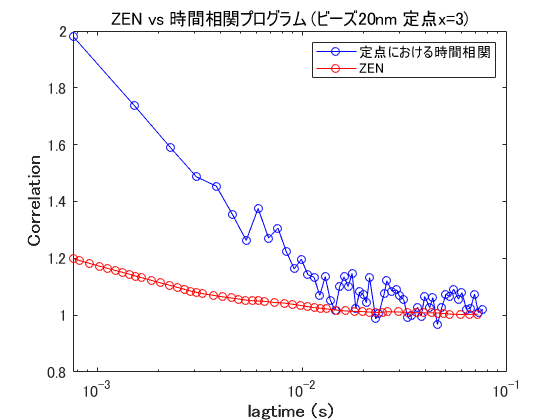

semilogx(TAU,COR, "b-o");
ax = gca; % current axes
ax.FontSize = 12;
xlabel("lagtime (s)", 'FontSize',14,'FontWeight','bold');
ylabel("Correlation", 'FontSize',14,'FontWeight','bold');

hold on;

semilogx(TAU_zen, COR_zen, "r-o")
legend("定点における時間相関", "ZEN", 'Location','northeast');

hold off;
title(sprintf("ZEN vs 時間相関プログラム (ビーズ%s 定点%s)", beads_size, POINT));
saveas(gcf, sprintf("output/zen_%s/%s/range_%s",DATE,POINT,figurename))

そのACFのτ＝０の点を基準に規格化→1~2

①cor -1 をすることで、1<cor<2　→　0<cor<1にする。

②co

COR_normalized = COR-1

COR_normalized =     0.9814    0.9814    0.9814    0.9814    0.9814    0.9814    0.9814    0.9814    0.9814    0.7361    0.7361    0.7361    0.7361    0.7361    0.7361    0.7361    0.7361    0.7361    0.7361    0.7361    0.5884    0.5884    0.5884    0.5884    0.5884    0.5884    0.5884    0.4867    0.4867    0.4867    0.4867    0.4867    0.4867    0.4542    0.4542    0.4542    0.4542    0.3540    0.3540    0.3540    0.3540    0.2632    0.2632    0.2632    0.3757    0.3757    0.3757    0.2713    0.2713    0.3066


COR_zen_normalized = COR_zen -1

COR_zen_normalized =     0.1990
    0.1924
    0.1820
    0.1728
    0.1644
    0.1572
    0.1507
    0.1444
    0.1377
    0.1325


SCALE = COR_zen_normalized(1) / COR_normalized(1)

SCALE = 0.2028

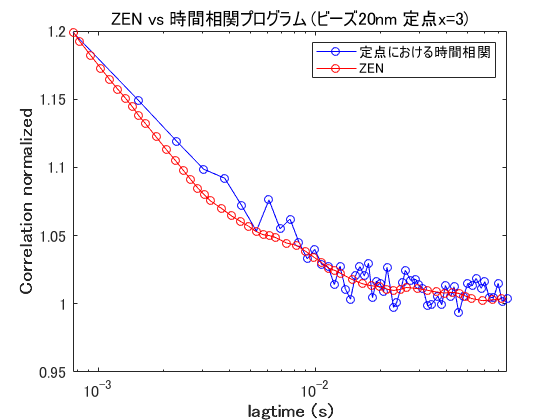

COR_normalized2zen = COR_normalized .* SCALE;

COR_normalized2zen = COR_normalized2zen + 1;
COR_zen_normalized = COR_zen_normalized + 1;

semilogx(TAU, COR_normalized2zen, "b-o")
hold on;
semilogx(TAU_zen, COR_zen_normalized, "r-o")
xlim([TIME_SCALE TIME_SCALE*TAU_MAX])
legend("定点における時間相関", "ZEN", 'Location','northeast');

ax = gca; % current axes
ax.FontSize = 12;
xlabel("lagtime (s)", 'FontSize',14,'FontWeight','bold');
ylabel("Correlation normalized", 'FontSize',14,'FontWeight','bold');

hold off;
title(sprintf("ZEN vs 時間相関プログラム (ビーズ%s 定点%s)", beads_size, POINT));
saveas(gcf, sprintf("output/zen_%s/%s/normalized_%s",DATE,POINT,figurename))

全体のτについて(not normalized)

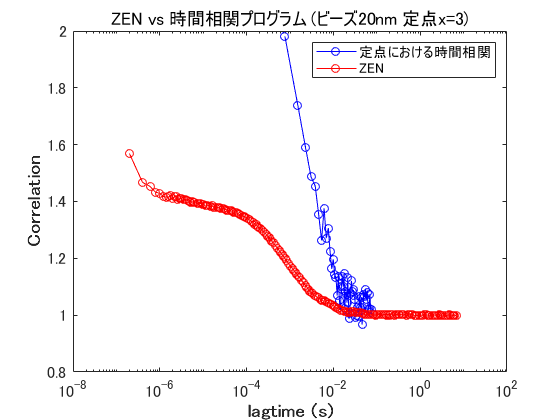

semilogx(TAU,COR, "b-o");
ax = gca; % current axes
ax.FontSize = 12;
xlabel("lagtime (s)", 'FontSize',14,'FontWeight','bold');
ylabel("Correlation", 'FontSize',14,'FontWeight','bold');

hold on;

semilogx(zen_matrix(:,1),zen_matrix(:,2), "r-o")
legend("定点における時間相関", "ZEN", 'Location','northeast');

hold off;
title(sprintf("ZEN vs 時間相関プログラム (ビーズ%s 定点%s)", beads_size, POINT));
saveas(gcf, sprintf("output/zen_%s/%s/overall_notNormalized_%s",DATE,POINT,figurename))